# Importing .csv File

clc, clear all, format compact 

sf_data = readtable("ca_san_francisco_2020_04_01.csv")

sf_data = 905070×22 table
    raw_row_number       date         time                location                lat        lng      district    subject_age           subject_race           subject_sex        type         arrest_made    citation_issued    warning_issued      outcome       contraband_found    search_conducted    search_vehicle    search_basis                   reason_for_stop                   raw_search_vehicle_description    raw_result_of_contact_description
    ______________    __________    ________    _____________________________    <

# Filtering to Just 2015 Data

clc, clearvars -except sf_data
SF_timedata = table2timetable(sf_data);        
sf_2015_data = SF_timedata(timerange('2015-01-01', '2016-01-01'), :)

sf_2015_data = 85998×21 timetable
       date       raw_row_number      time                location                lat        lng      district    subject_age           subject_race           subject_sex        type         arrest_made    citation_issued    warning_issued      outcome       contraband_found    search_conducted    search_vehicle    search_basis                   reason_for_stop                         raw_search_vehicle_description           raw_result_of_contact_description
    __________    ______________    ________    ______________________

# Line graph for Stops by Date

sf_2015_individual_dates = groupsummary(sf_2015_data, {'date'})

sf_2015_individual_dates = 365×2 table
       date       GroupCount
    __________    __________
    2015-01-01       179    
    2015-01-02       266    
    2015-01-03       306    
    2015-01-04       291    
    2015-01-05       272    
    2015-01-06       290    
    2015-01-07       299    
    2015-01-08       351    
    2015-01-09       312    
    2015-01-10       270    
    2015-01-11       305    
    2015-01-12       267    
    2015-01-13       262    
    2015-01-14       268    
    2015-01-15       277    
    2015-01-16       298    

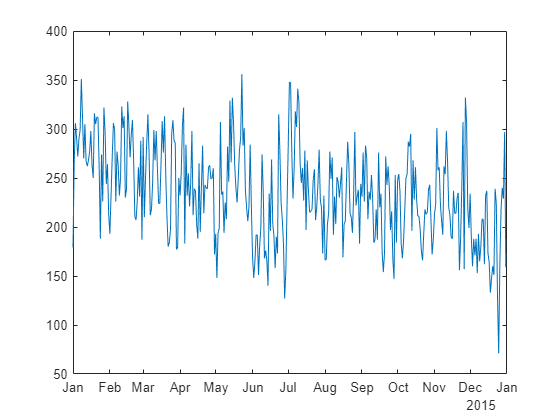

%whole year
plot(sf_2015_individual_dates.date, sf_2015_individual_dates.GroupCount)

sf_2015_individual_dates_timetable = table2timetable(sf_2015_individual_dates);
sf_2015_march = sf_2015_individual_dates_timetable(timerange('2015-03-01', 'months'), :)

sf_2015_march = 31×1 timetable
       date       GroupCount
    __________    __________
    2015-03-01       292    
    2015-03-02       210    
    2015-03-03       251    
    2015-03-04       286    
    2015-03-05       315    
    2015-03-06       274    
    2015-03-07       212    
    2015-03-08       218    
    2015-03-09       246    
    2015-03-10       299    
    2015-03-11       268    
    2015-03-12       298    
    2015-03-13       259    
    2015-03-14       224    
    2015-03-15       224    
    2015-03-16       263    

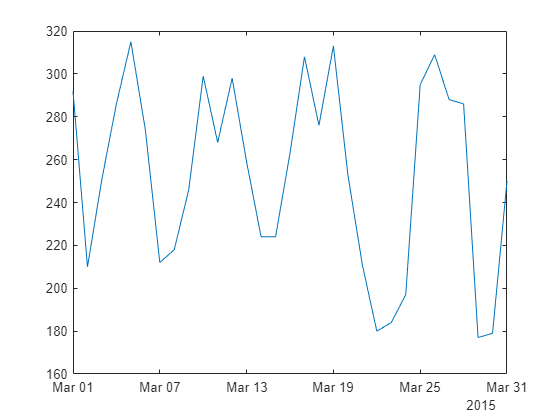

%monthly 
plot(sf_2015_march.date, sf_2015_march.GroupCount)

[dayNumber, dayNames] = weekday(sf_2015_individual_dates.date);
sf_2015_individual_dayofweek = [sf_2015_individual_dates array2table(dayNumber)];
sf_2015_individual_dayofweek = table(sf_2015_individual_dayofweek.dayNumber, sf_2015_individual_dayofweek.GroupCount, 'VariableNames', {'DayofWeek', 'NumberOfStops'})

sf_2015_individual_dayofweek = 365×2 table
    DayofWeek    NumberOfStops
    _________    _____________
        5             179     
        6             266     
        7             306     
        1             291     
        2             272     
        3             290     
        4             299     
        5             351     
        6             312     
        7             270     
        1             305     
        2             267     
        3             262     
        4             268     
        5             277     
        6             298     

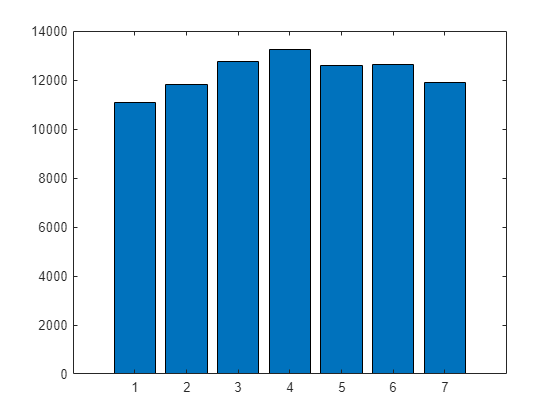

number_of_stops_perday = groupsummary(sf_2015_individual_dayofweek, 'DayofWeek', 'sum');
number_of_stops_perday(:,2) = [];
bar(number_of_stops_perday.DayofWeek, number_of_stops_perday.sum_NumberOfStops)

# Reasons for Stop

sf_2015_reasonsforstop = groupsummary(sf_2015_data, {'reason_for_stop'});

%removing outlier reasons for stop
sf_2015_reasonsforstop = sf_2015_reasonsforstop(sf_2015_reasonsforstop.GroupCount >2, {'reason_for_stop', 'GroupCount'})

sf_2015_reasonsforstop = 8×2 table
                   reason_for_stop                   GroupCount
    _____________________________________________    __________
    {'Assistance to Motorist'                   }        194   
    {'BOLO/APB/Warrant'                         }        191   
    {'DUI Check'                                }         77   
    {'MPC Violation'                            }        855   
    {'Mechanical or Non-Moving Violation (V.C.)'}      31129   
    {'Moving Violation'                         }      52895   
    {'NA'                                       }        432   
    {'Traffic Collision'                        }        219   

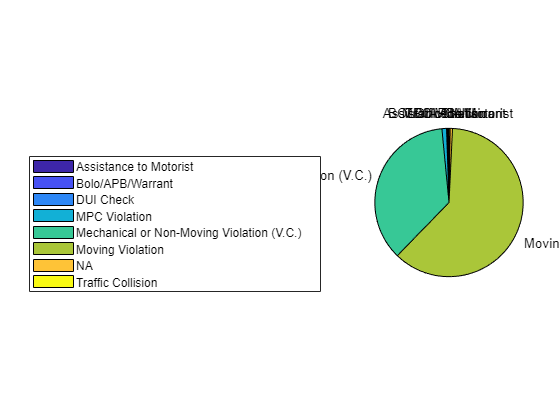

pie(sf_2015_reasonsforstop.GroupCount, sf_2015_reasonsforstop.reason_for_stop);
labels = {'Assistance to Motorist','Bolo/APB/Warrant','DUI Check', 'MPC Violation', 'Mechanical or Non-Moving Violation (V.C.)', 'Moving Violation', 'NA', 'Traffic Collision'};
legend(labels, 'Location', 'southwestoutside')

# Benchmark Test

 sf_2015_grouped_by_race = groupsummary(sf_2015_data, {'subject_race'});
 sf_2015_grouped_by_race.Properties.VariableNames{2} = 'Number of Police Stops (2015)'

sf_2015_grouped_by_race = 5×2 table
           subject_race           Number of Police Stops (2015)
    __________________________    _____________________________
    {'asian/pacific islander'}                15530            
    {'black'                 }                14990            
    {'hispanic'              }                11943            
    {'other'                 }                13668            
    {'white'                 }                29867            


population_2015 = [284000; 46800; 129000; 38000; 347000];
sf_stops_population_2015 = [sf_2015_grouped_by_race array2table(population_2015)]

sf_stops_population_2015 = 5×3 table
           subject_race           Number of Police Stops (2015)    population_2015
    __________________________    _____________________________    _______________
    {'asian/pacific islander'}                15530                   2.84e+05    
    {'black'                 }                14990                      46800    
    {'hispanic'              }                11943                   1.29e+05    
    {'other'                 }                13668                      38000    
    {'white'                 }                29867                   3.47e+05    

stop_rates = sf_stops_population_2015.("Number of Police Stops (2015)")./sf_stops_population_2015.population_2015;
sf_stops_population_2015 = [sf_stops_population_2015 array2table(stop_rates)]

sf_stops_population_2015 = 5×4 table
           subject_race           Number of Police Stops (2015)    population_2015    stop_rates
    __________________________    _____________________________    _______________    __________
    {'asian/pacific islander'}                15530                   2.84e+05         0.054683 
    {'black'                 }                14990                      46800           0.3203 
    {'hispanic'              }                11943                   1.29e+05         0.092581 
    {'other'                 }                13668                      38000          0.35968 
    {'white'                 }                29867                   3.47e+05         0.086072 

# Search Rate: proportion of stopped people who were subsequently searched

race_and_search = array2table(sf_2015_data{:,["subject_race", "search_conducted"]})

race_and_search = 85998×2 table
               Var1                 Var2   
    __________________________    _________
    {'black'                 }    {'FALSE'}
    {'hispanic'              }    {'FALSE'}
    {'white'                 }    {'FALSE'}
    {'white'                 }    {'FALSE'}
    {'white'                 }    {'FALSE'}
    {'white'                 }    {'FALSE'}
    {'asian/pacific islander'}    {'FALSE'}
    {'asian/pacific islander'}    {'FALSE'}
    {'asian/pacific islander'}    {'FALSE'}
    {'other'                 }    {'FALSE'}
    {'black'                 }    {'FALSE'}
    {'white'                 }    {'FALSE'}
    {'white'                 }    {'FALSE'}
    {'white'                 }    {'TRUE' }
    {'other'                 }    {'FALSE'}
    {'black'                 }    {'FALSE'}

%converting 'TRUE'/'False' to 1/0

t_f = race_and_search{:,["Var2"]};
t_f = strcmp(t_f, 'TRUE');
race_and_search = [race_and_search array2table(t_f)];
race_and_search.Var2 = [];
race_and_search.Properties.VariableNames{1} = 'subject_race';
race_and_search.Properties.VariableNames{2} = 'Search Conducted?'

race_and_search = 85998×2 table
           subject_race           Search Conducted?
    __________________________    _________________
    {'black'                 }          false      
    {'hispanic'              }          false      
    {'white'                 }          false      
    {'white'                 }          false      
    {'white'                 }          false      
    {'white'                 }          false      
    {'asian/pacific islander'}          false      
    {'asian/pacific islander'}          false      
    {'asian/pacific islander'}          false      
    {'other'                 }          false      
    {'black'                 }          false      
    {'white'                 }          false      
    {'white'                 }          false      
    {'white'                 }          true       
    {'other'                 }          false      
    {'black'    

race_and_search = groupsummary(race_and_search, "subject_race", "mean");

VariableNames = ["subject_race" "Number of Searches (2015)" "Search Rate (2015)"];
race_and_search.Properties.VariableNames = VariableNames

race_and_search = 5×3 table
           subject_race           Number of Searches (2015)    Search Rate (2015)
    __________________________    _________________________    __________________
    {'asian/pacific islander'}              15530                   0.012492     
    {'black'                 }              14990                    0.15637     
    {'hispanic'              }              11943                   0.063719     
    {'other'                 }              13668                    0.01734     
    {'white'                 }              29867                   0.022165     

# Outcome Test

sf_2015_search_happened = sf_2015_data(strcmp(sf_2015_data.search_conducted, 'TRUE'), ["district", "subject_race", "search_conducted", "contraband_found"])

sf_2015_search_happened = 4198×4 timetable
       date       district    subject_race    search_conducted    contraband_found
    __________    ________    ____________    ________________    ________________
    2015-01-01     {'I'}      {'white'   }        {'TRUE'}           {'TRUE' }    
    2015-01-01     {'D'}      {'black'   }        {'TRUE'}           {'TRUE' }    
    2015-01-01     {'C'}      {'black'   }        {'TRUE'}           {'FALSE'}    
    2015-01-01     {'H'}      {'hispanic'}        {'TRUE'}           {'FALSE'}    
    2015-01-01     {'D'}      {'white'   }        {'TRUE'}           {'FALSE'}    
    2015-01-01     {'C'}      {'black'   }        {'TRUE'}           {'FALSE'}    
    2015-01-0

[sf_2015_search_conducted_int, sf_2015_contraband_found_int] = TF_conversion(sf_2015_search_happened.search_conducted, sf_2015_search_happened.contraband_found);

varargout = 1×1 cell array
    {4198×1 logical}

varargout = 1×2 cell array
    {4198×1 logical}    {4198×1 logical}

sf_2015_search_happened = [sf_2015_search_happened array2table(sf_2015_search_conducted_int) array2table(sf_2015_contraband_found_int)];
sf_2015_search_happened(:,3:4) = [];
hit_rate_race_district = groupsummary(sf_2015_search_happened, ["subject_race", "district"], "mean", "sf_2015_contraband_found_int");
hit_rate_race_district(:,3) = [];
hit_rate_race_district.Properties.VariableNames = ["subject_race", "district", "hit rate"]

hit_rate_race_district = 56×3 table
           subject_race           district    hit rate
    __________________________    ________    ________
    {'asian/pacific islander'}     {'A'}       0.52941
    {'asian/pacific islander'}     {'B'}       0.28571
    {'asian/pacific islander'}     {'C'}           0.4
    {'asian/pacific islander'}     {'D'}       0.30769
    {'asian/pacific islander'}     {'E'}       0.28571
    {'asian/pacific islander'}     {'F'}           0.8
    {'asian/pacific islander'}     {'G'}        0.4375
    {'asian/pacific islander'}     {'H'}       0.19512
    {'asian/pacific islander'}     {'I'}       0.52778
    {'asian/pacific islander'}     {'J'}       0.22222
    {'black'                 }     {'A'}       0.18987
    {'black'                 }     {'B'}       0.18301
    {'black'                 }     {'C'}       0.10532
    {'black'                 }     {'

white_hit_rates = hit_rate_race_district(strcmp(hit_rate_race_district.subject_race, 'white'), :)

white_hit_rates = 12×3 table
    subject_race    district    hit rate
    ____________    ________    ________
     {'white'}       {'A'}      0.33333 
     {'white'}       {'B'}      0.32258 
     {'white'}       {'C'}      0.14286 
     {'white'}       {'D'}      0.27907 
     {'white'}       {'E'}      0.24096 
     {'white'}       {'F'}         0.58 
     {'white'}       {'G'}      0.43902 
     {'white'}       {'H'}      0.22727 
     {'white'}       {'I'}      0.31081 
     {'white'}       {'J'}      0.22857 
     {'white'}       {'S'}            0 
     {'white'}       {'T'}            1 

black_hit_rates = hit_rate_race_district(strcmp(hit_rate_race_district.subject_race, 'black'), :)

black_hit_rates = 12×3 table
    subject_race    district    hit rate
    ____________    ________    ________
     {'black'}       {'A'}       0.18987
     {'black'}       {'B'}       0.18301
     {'black'}       {'C'}       0.10532
     {'black'}       {'D'}         0.139
     {'black'}       {'E'}      0.081545
     {'black'}       {'F'}       0.16667
     {'black'}       {'G'}      0.078947
     {'black'}       {'H'}       0.09596
     {'black'}       {'I'}       0.10938
     {'black'}       {'J'}        0.2153
     {'black'}       {'S'}             0
     {'black'}       {'T'}             1

hispanic_hit_rates = hit_rate_race_district(strcmp(hit_rate_race_district.subject_race, 'hispanic'), :)

hispanic_hit_rates = 11×3 table
    subject_race    district    hit rate
    ____________    ________    ________
    {'hispanic'}     {'A'}         0.25 
    {'hispanic'}     {'B'}      0.17308 
    {'hispanic'}     {'C'}         0.19 
    {'hispanic'}     {'D'}       0.2029 
    {'hispanic'}     {'E'}      0.19048 
    {'hispanic'}     {'F'}      0.30769 
    {'hispanic'}     {'G'}      0.23529 
    {'hispanic'}     {'H'}      0.13453 
    {'hispanic'}     {'I'}      0.34783 
    {'hispanic'}     {'J'}      0.23529 
    {'hispanic'}     {'T'}            1 

num_searches_per_district = groupsummary(sf_2015_search_happened, "district");
white_black_hit_rates = join(white_hit_rates, black_hit_rates, 'Keys', 'district');
white_black_hit_rates = join(white_black_hit_rates, num_searches_per_district, 'Keys', 'district')

white_black_hit_rates = 12×6 table
    subject_race_white_hit_rates    district    hit rate_white_hit_rates    subject_race_black_hit_rates    hit rate_black_hit_rates    GroupCount
    ____________________________    ________    ________________________    ____________________________    ________________________    __________
             {'white'}               {'A'}              0.33333                      {'black'}                       0.18987                185   
             {'white'}               {'B'}              0.32258                      {'black'}                       0.18301                343   
             {'white'}               {'C'}              0.14286                      {'black'}                       0.10532               1163   
             {'white'}    

white_hit_rates

white_hit_rates = 12×3 table
    subject_race    district    hit rate
    ____________    ________    ________
     {'white'}       {'A'}      0.33333 
     {'white'}       {'B'}      0.32258 
     {'white'}       {'C'}      0.14286 
     {'white'}       {'D'}      0.27907 
     {'white'}       {'E'}      0.24096 
     {'white'}       {'F'}         0.58 
     {'white'}       {'G'}      0.43902 
     {'white'}       {'H'}      0.22727 
     {'white'}       {'I'}      0.31081 
     {'white'}       {'J'}      0.22857 
     {'white'}       {'S'}            0 
     {'white'}       {'T'}            1 

white_hispanic_hit_rates = join(white_hit_rates(~strcmp(white_hit_rates.district,'S'), :), hispanic_hit_rates, 'Keys', 'district');
white_hispanic_hit_rates = join(white_hispanic_hit_rates, num_searches_per_district)

white_hispanic_hit_rates = 11×6 table
    subject_race_left    district    hit rate_left    subject_race_hispanic_hit_rates    hit rate_hispanic_hit_rates    GroupCount
    _________________    ________    _____________    _______________________________    ___________________________    __________
        {'white'}         {'A'}         0.33333                {'hispanic'}                           0.25                  185   
        {'white'}         {'B'}         0.32258                {'hispanic'}                        0.17308                  343   
        {'white'}         {'C'}         0.14286                {'hispanic'}                           0.19                 1163   
        {'white'}         {'D'}         0.27907                {'hispanic'}                         0.2

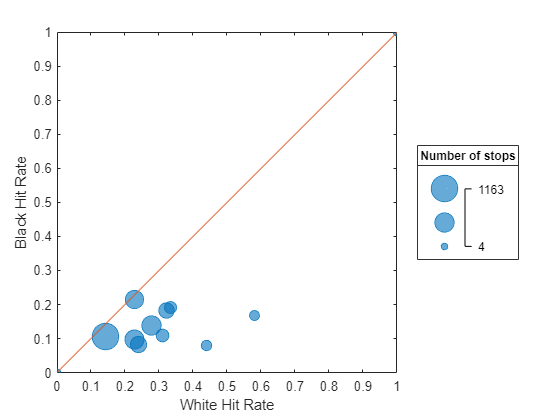

bubblechart(white_black_hit_rates.("hit rate_white_hit_rates"), white_black_hit_rates.("hit rate_black_hit_rates"), white_black_hit_rates.GroupCount)
bubblesize([5 20])
set(gca,'xtick',linspace(0,1,11),'ytick',linspace(0,1,11))
xlabel('White Hit Rate')
ylabel('Black Hit Rate')
bubblelegend('Number of stops','Location','eastoutside')
hold on
plot([0 1], [0,1])
axis square
hold off

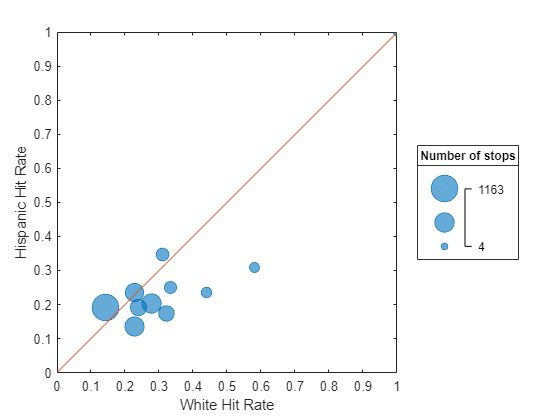



bubblechart(white_hispanic_hit_rates.("hit rate_left"), white_hispanic_hit_rates.("hit rate_hispanic_hit_rates"), white_hispanic_hit_rates.GroupCount)
bubblesize([5 20])
set(gca,'xtick',linspace(0,1,11),'ytick',linspace(0,1,11))
xlabel('White Hit Rate')
ylabel('Hispanic Hit Rate')
bubblelegend('Number of stops','Location','eastoutside')
hold on
plot([0 1], [0,1])
axis square